%Clear all older variables
clear
close all
clc

# System Parameters


%%parameters
r= 2;
m= 1;
c =1;
k =10;
k_1=k;
k_2=k;
k_3=k;
m_1=m;
m_2=m*r;
c_1=c;
c_2=c;
c_3=c;

# System Matrices

A = [0, 1, 0, 0; -(k_1+k_3)/m_1, -(c_1+c_3)/m_1, k_3/m_1, c_3/m_1; 0, 0, 0, 1; k_3/m_2, c_3/m_2, -(k_2+k_3)/m_2, -(c_2+c_3)/m_2]

A =          0    1.0000         0         0
  -20.0000   -2.0000   10.0000    1.0000
         0         0         0    1.0000
    5.0000    0.5000  -10.0000   -1.0000


B = [0,0; 1/m_1,0; 0,0;0,1/m_2]

B =          0         0
    1.0000         0
         0         0
         0    0.5000


C = eye(4);
D = zeros(4,2);
system_DL= ss(A,B,C,D);

# Pole Placement

k = place(A,B(:,1), ([-1,-2,-3,-4]));

# Closed Loop System

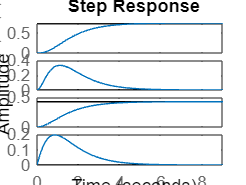

A_cl = A-B(:,1)*k;
B_cl = B(:,2);
C_cl = C;
D_cl    = zeros(4,1);
system_Cl = ss(A_cl,B_cl,C_cl,D_cl);
figure
step(system_Cl)

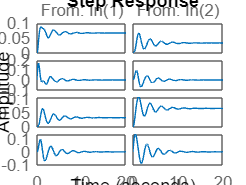

figure
step(system_DL)